# **Assignment 5**

# **Use of Matlab to investigate compartmental systems**

#### Wickramasinghe S.D. - 220700T

## **Part 1**

#### **Question 1**

**Unit step input  - normal**

The code for the system as yp = ax + b format can be found in the file *normal_unitstep.m* as a function. 

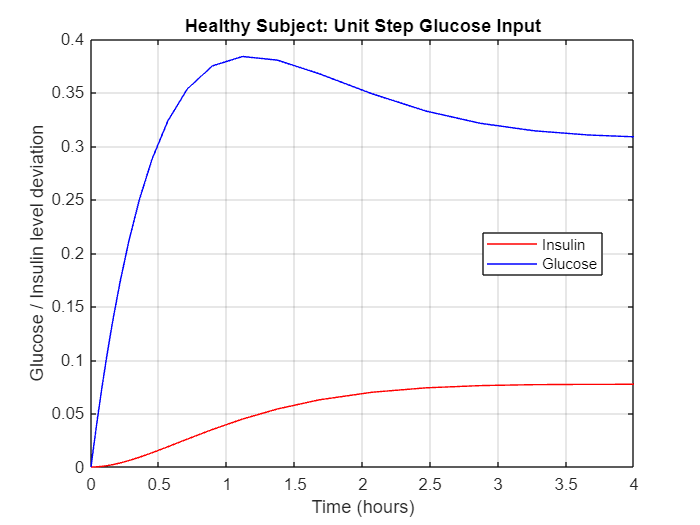

% Solve the system using ode23
[t, y] = ode23('normal_unitstep', [0,4], [0,0]);

% Plot the reuslts
figure;
plot(t, y(:,1), 'r-','DisplayName', 'Insulin'); hold on;
plot(t, y(:,2), 'b-','DisplayName', 'Glucose');
legend('Location', 'best');
xlabel('Time (hours)');
ylabel('Glucose / Insulin level deviation');
title('Healthy Subject: Unit Step Glucose Input');
grid on;

**Bolus Input - Normal**

The code for the system as yp = ax + b format can be found in the file *normal_bolus.m* as a function.

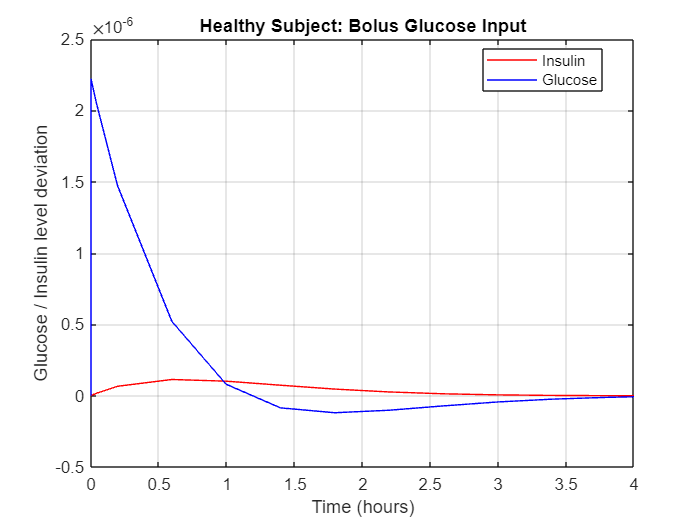

    [t, y] = ode23('normal_bolus', [0,4], [0,0]);

    figure;
    plot(t, y(:,1), 'r-','DisplayName', 'Insulin'); hold on;
    plot(t, y(:,2), 'b-','DisplayName', 'Glucose');
    legend('Location', 'best');
    xlabel('Time (hours)');
    ylabel('Glucose / Insulin level deviation');
    title('Healthy Subject: Bolus Glucose Input');
    grid on;

**Unit step input - Diabitic patient**

The code for the system as yp = ax + b format can be found in the file *diabetic_unitstep.m* as a function.

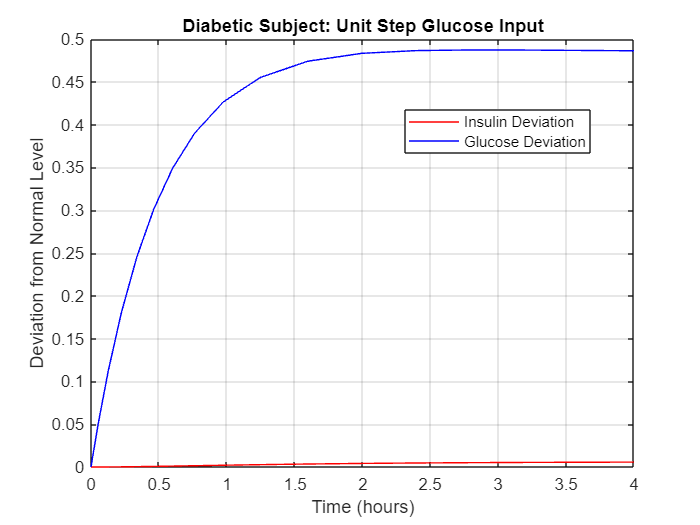

[t, y] = ode23('diabetic_unitstep', [0,4],[0,0]);

figure;
plot(t, y(:,1), 'r-','DisplayName', 'Insulin Deviation');
hold on;
plot(t, y(:,2), 'b-','DisplayName', 'Glucose Deviation');
legend('Location', 'best');
xlabel('Time (hours)');
ylabel('Deviation from Normal Level');
title('Diabetic Subject: Unit Step Glucose Input');
grid on;

**Insulin Injection - Diabitic patient**

The code for the system as yp = ax + b format can be found in the file *diabetic_with_insulin.m* as  a function.

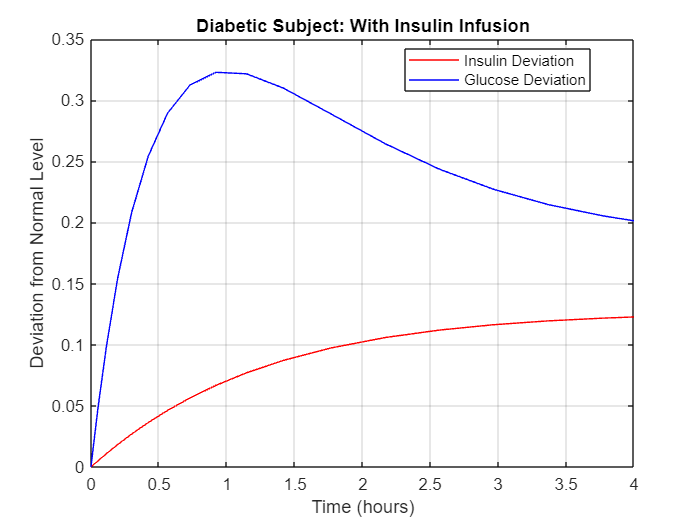

[t, y] = ode23('diabetic_with_insulin', [0,4],[0,0]);

figure;
plot(t, y(:,1), 'r-','DisplayName', 'Insulin Deviation');
hold on;
plot(t, y(:,2), 'b-','DisplayName', 'Glucose Deviation');
legend('Location', 'best');
xlabel('Time (hours)');
ylabel('Deviation from Normal Level');
title('Diabetic Subject: With Insulin Infusion');
grid on;

#### **Question 2**

**Riggs model output for iodine input 150 ug/d **

The code for the system as yp = ax + b format can be found in the file* riggs_model_150.m* as a function.

**10 days**

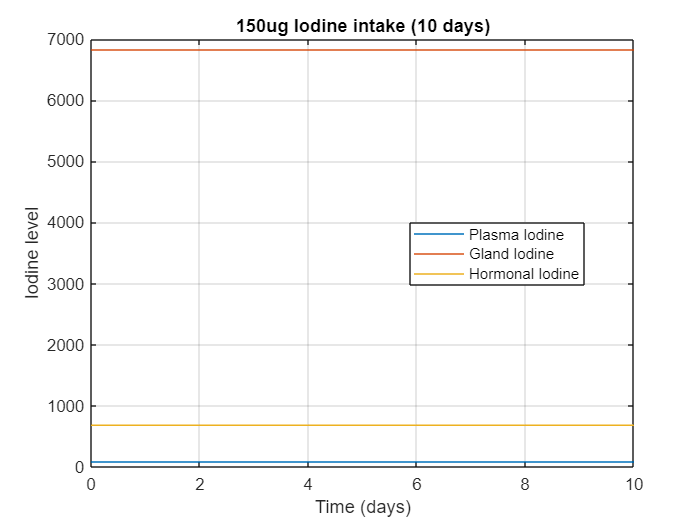

[t,y] = ode23('riggs_model_150',[0 10],[81.2 6821 682]);

figure;
plot(t,y); grid on;
xlabel('Time (days)');
ylabel('Iodine level');
title('150ug Iodine intake (10 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine','Location', 'best');

**300 days**

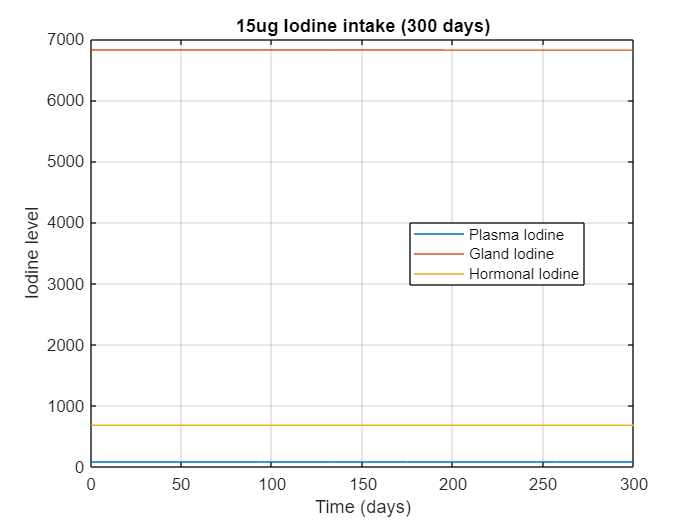

[t,y] = ode23('riggs_model_150',[0 300],[81.2 6821 682]);
figure;
plot(t,y); grid on;
xlabel('Time (days)');
ylabel('Iodine level');
title('15ug Iodine intake (300 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine','Location', 'best');

**Riggs model output for iodine input 15 ug/d **

The code for the system as yp = ax + b format can be found in the file* riggs_model_15.m* as a function.

**10 days**

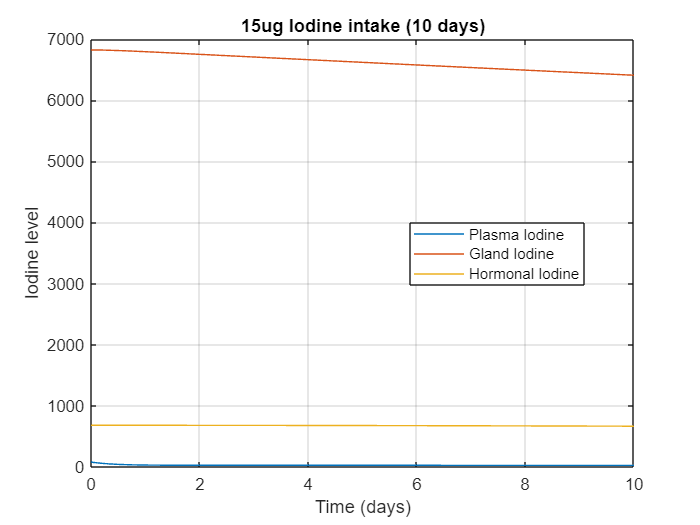

[t,y] = ode23('riggs_model_15',[0 10],[81.2 6821 682]);

figure;
plot(t,y); grid on;
xlabel('Time (days)');
ylabel('Iodine level');
title('15ug Iodine intake (10 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine','Location', 'best');

**300 days**

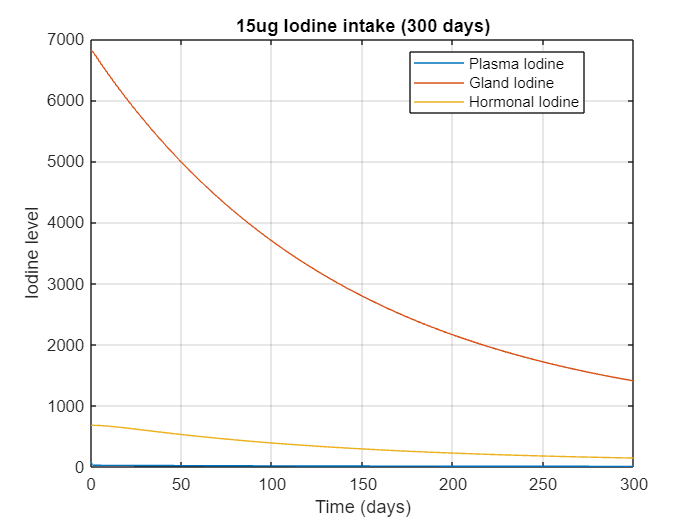

[t,y] = ode23('riggs_model_15',[0 300],[81.2 6821 682]);

figure;
plot(t,y); grid on;
xlabel('Time (days)');
ylabel('Iodine level');
title('15ug Iodine intake (300 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine','Location', 'best');

**a. Hypothyroidism due to autoimmune thyroid disease**

In hypothyroidism due to autoimmune thyroid disease (e.g., Hashimoto's thyroiditis), the thyroid gland is damaged and loses its ability to trap iodine and produce hormones. In the Riggs model, this is represented by a decrease in the iodine uptake rate (I → G) and a significant reduction in hormone production (G → H). These changes lead to lower glandular and hormonal iodine levels over time, resulting in a reduced steady-state of circulating thyroid hormones, which reflects the typical hormone deficiency seen in hypothyroidism.

The code for the system as yp = ax + b format can be found in the file* riggs_hypothyroidism.m* as a function.

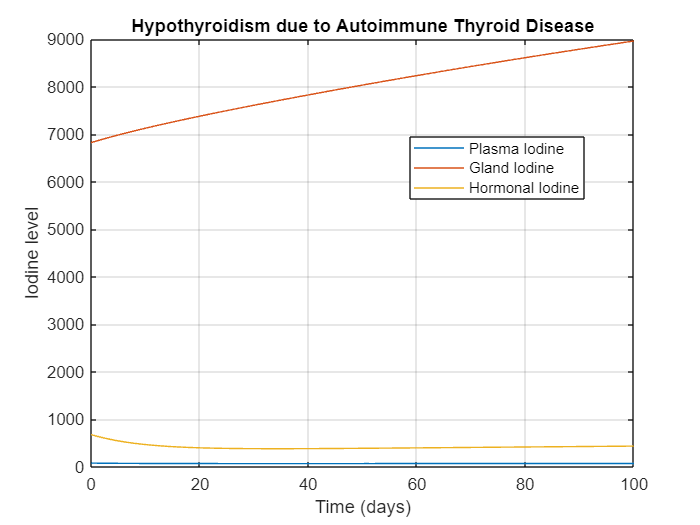

[t,y] = ode23('riggs_hypothyroidism',[0 100],[81.2 6821 682]);

figure;
plot(t,y); grid on;
xlabel('Time (days)');
ylabel('Iodine level');
title('Hypothyroidism due to Autoimmune Thyroid Disease');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine','Location', 'best');

**b. Hypothyroidism due to low Iodine intake ** 

In hypothyroidism caused by low iodine intake, the body lacks sufficient dietary iodine to support normal thyroid hormone production. In the Riggs model, this is reflected by a reduction in the iodine input term (from 15 to a lower value, e.g., 5 or 0), leading to decreased inorganic iodine (I) levels in plasma. As a result, less iodine is available for uptake into the thyroid (I → G), and thus glandular iodine (G) and hormonal iodine (H) levels also decline. This condition results in insufficient thyroid hormone synthesis, even though the thyroid gland itself may still be functional.

The code for the system as yp = ax + b format can be found in the file* riggs_hypothyroidism_low_iodine_intake.m* as a function.

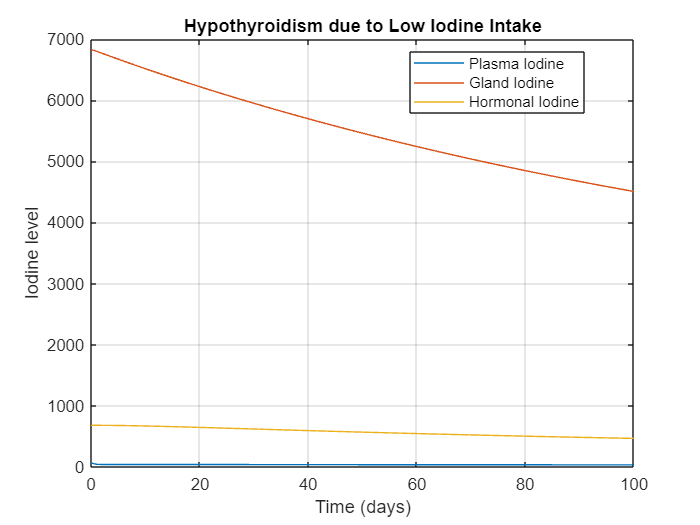

[t,y] = ode23('riggs_hypothyroidism_low_iodine_intake',[0 100],[81.2 6821 682]);
figure;
plot(t,y); grid on;
xlabel('Time (days)');
ylabel('Iodine level');
title('Hypothyroidism due to Low Iodine Intake');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine','Location', 'best')

**c. Hyperthyroidism due to Grave's disease**

In hyperthyroidism due to Grave's disease, the immune system produces antibodies (TSI – thyroid-stimulating immunoglobulins) that mimic TSH, continuously stimulating the thyroid gland to produce excessive hormones, regardless of normal feedback control. In the Riggs model, this condition is modeled by increasing the rate of hormone synthesis from glandular iodine (i.e., increasing the G → H parameter) and possibly decreasing hormone degradation.. As a result, hormonal iodine (H) levels rise significantly and remain elevated, representing the overproduction of T3/T4 seen in Grave’s disease, despite low TSH levels due to disrupted feedback.

The code for the system as yp = ax + b format can be found in the file* riggs_hyperthyroidism.m* as a function.

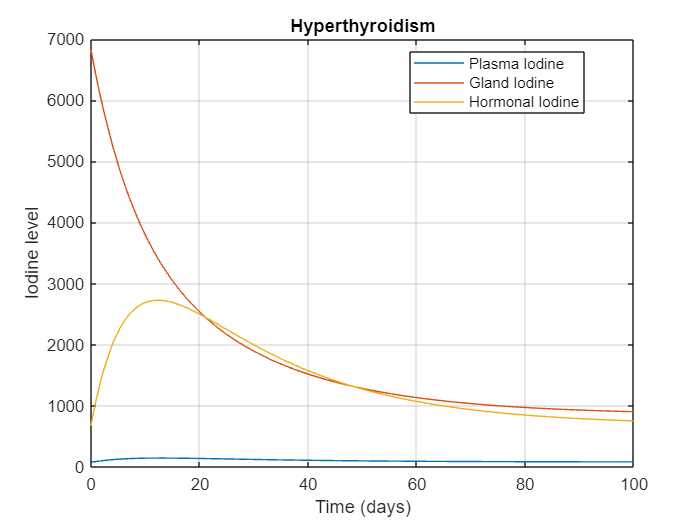

[t,y] = ode23('riggs_hyperthyroidism',[0 100],[81.2 6821 682]);
figure;
plot(t,y); grid on;
xlabel('Time (days)');
ylabel('Iodine level');
title('Hyperthyroidism');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine','Location', 'best')

**d. What are some common causes of goitre and tumors and how can they be simulated  in the Riggs' model? **

**Goitre**

Goitre is an abnormal enlargement of the thyroid gland, commonly caused by iodine deficiency, autoimmune diseases (like Hashimoto’s or Grave’s), or hormonal imbalances. In iodine deficiency, low dietary iodine leads to decreased hormone production, causing the pituitary to release more TSH, which overstimulates the thyroid and leads to gland enlargement. In the Riggs model, this can be simulated by reducing the iodine input, which decreases plasma iodine (I), lowers hormone production (H), and could cause a compensatory rise in glandular iodine (G) as the thyroid attempts to trap more iodine.

The code for the system as yp = ax + b format can be found in the file* riggs_goitre.m* as a function.

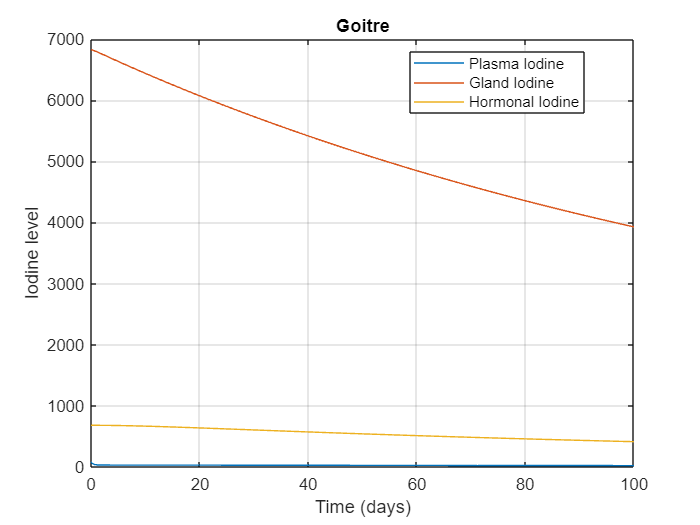

[t,y] = ode23('riggs_goitre',[0 100],[81.2 6821 682]);
figure;
plot(t,y); grid on;
xlabel('Time (days)');
ylabel('Iodine level');
title('Goitre');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine','Location', 'best')

**Tumor**

Thyroid tumors, whether benign (adenomas) or malignant (carcinomas), can alter hormone production depending on their nature. Functional tumors may overproduce hormones, leading to hyperthyroidism, while non-functional tumors may displace normal tissue, reducing hormone output. In the Riggs model, functional tumors can be simulated by increasing the G → H rate (e.g., from 0.01 to 0.02 or higher), representing excess hormone secretion. Non-functional tumors can be modeled by decreasing both the I → G and G → H parameters, simulating impaired iodine uptake and hormone synthesis due to loss of healthy thyroid tissue.

The code for the system as yp = ax + b format can be found in the file* riggs_tumor.m* as a function.

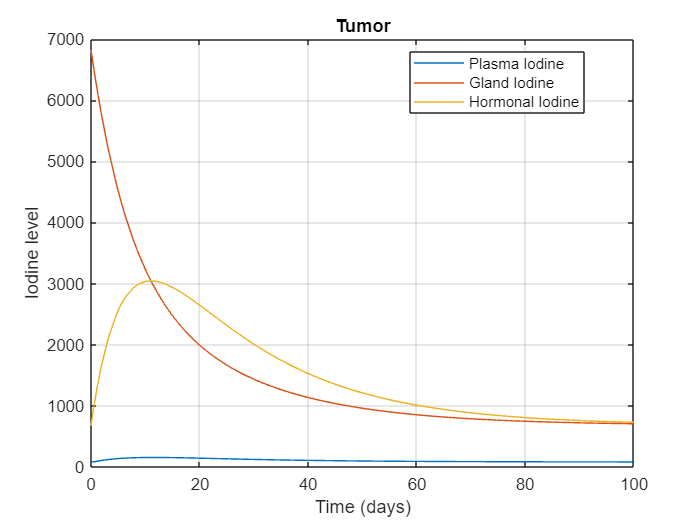

[t,y] = ode23('riggs_tumor',[0 100],[81.2 6821 682]);

figure;
plot(t,y); grid on;
xlabel('Time (days)');
ylabel('Iodine level');
title('Tumor');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine','Location', 'best')

## Part 2

#### Question 1

**Simulation of the equations solved in part 1**

The model in included in the *insulin_glucose.slx* file.

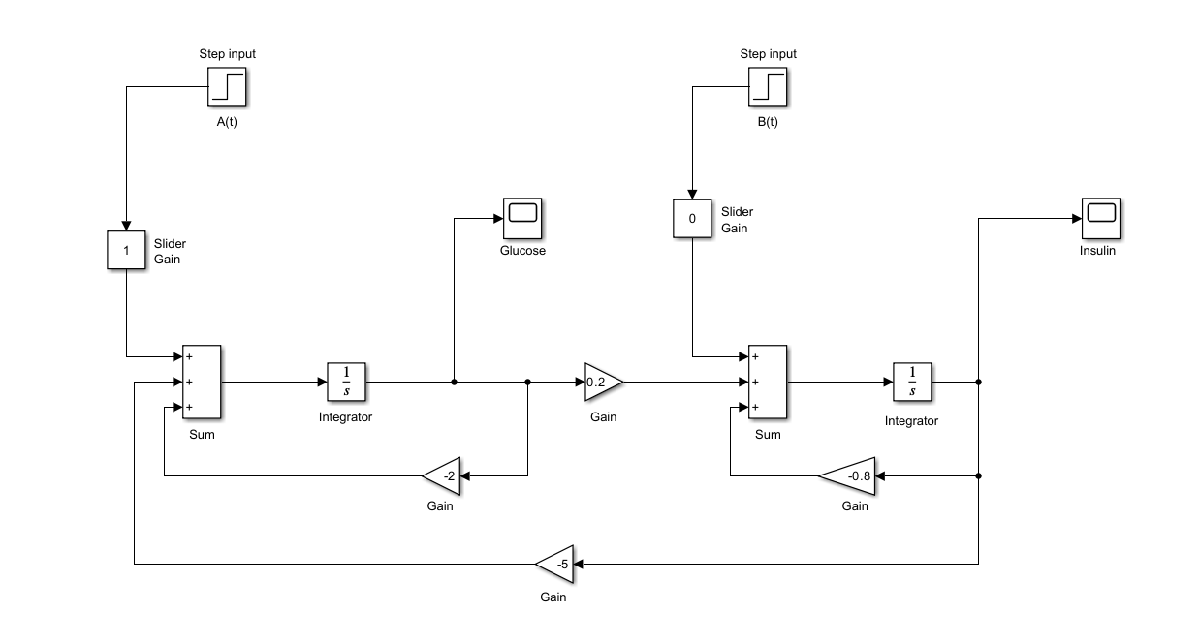

The results are as follows.

Glucose                                                                   

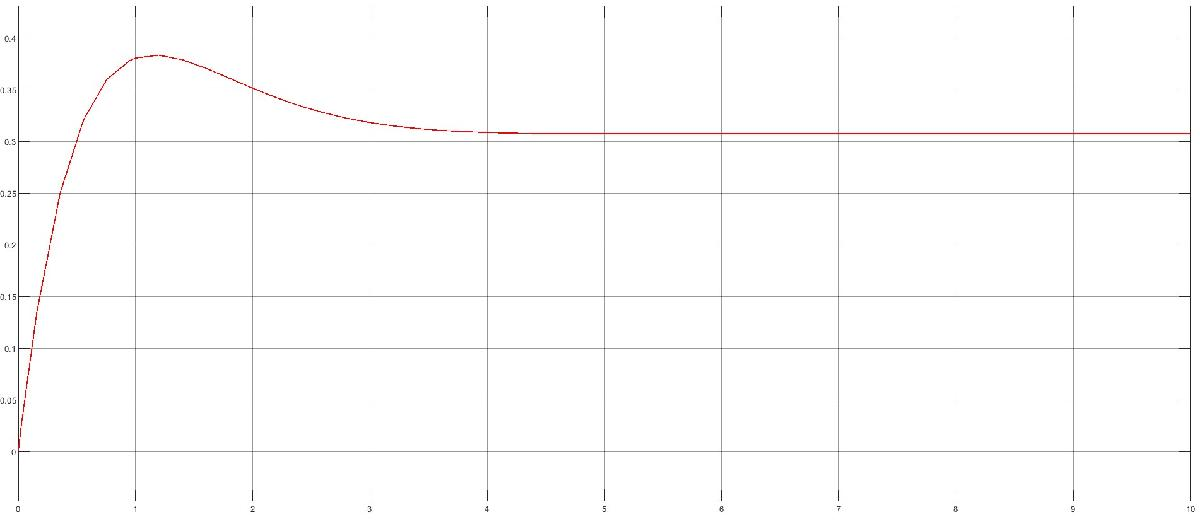      

Insulin

 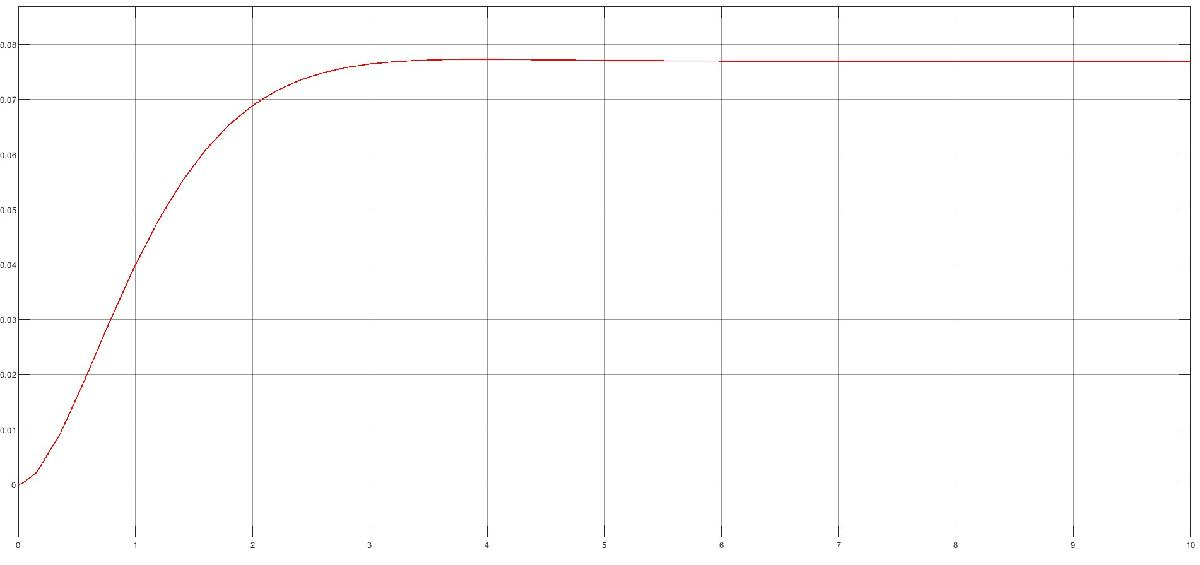

**Simulation for the alternate set of cofficients, determined by a different procedure in the original article**

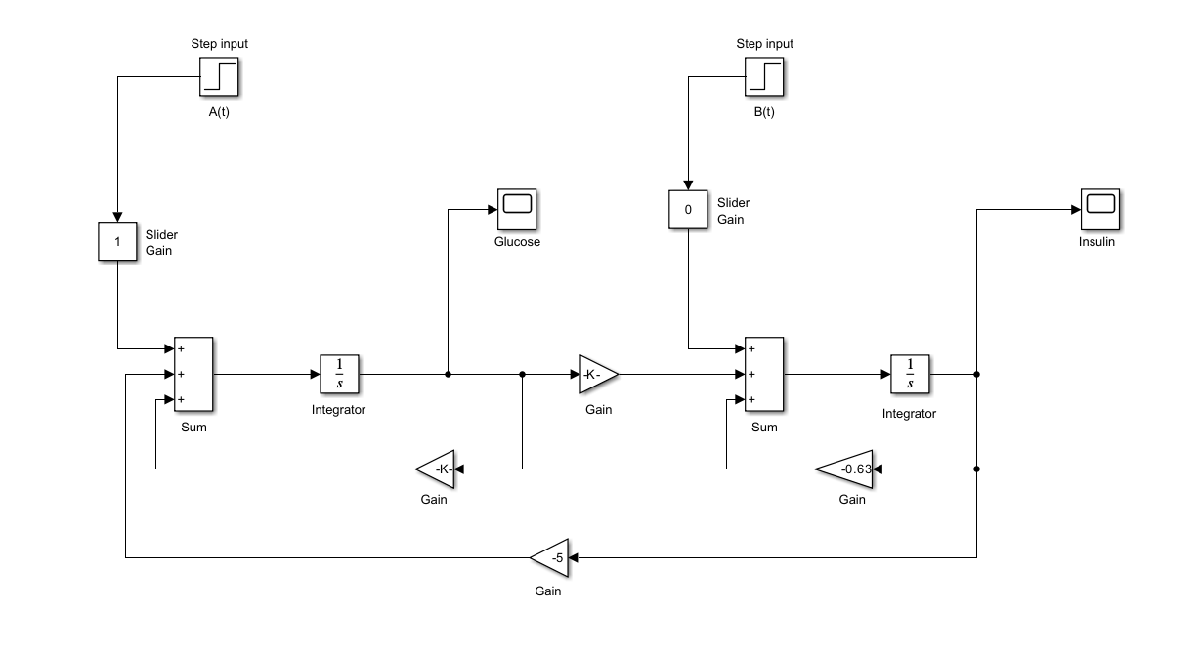

The results are as follows.

Glucose

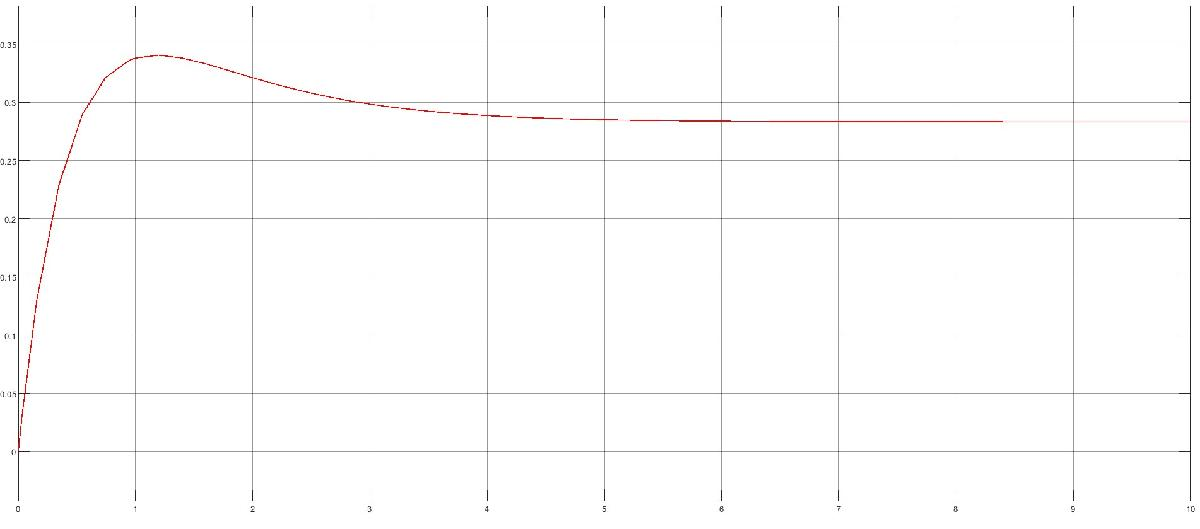

Insulin

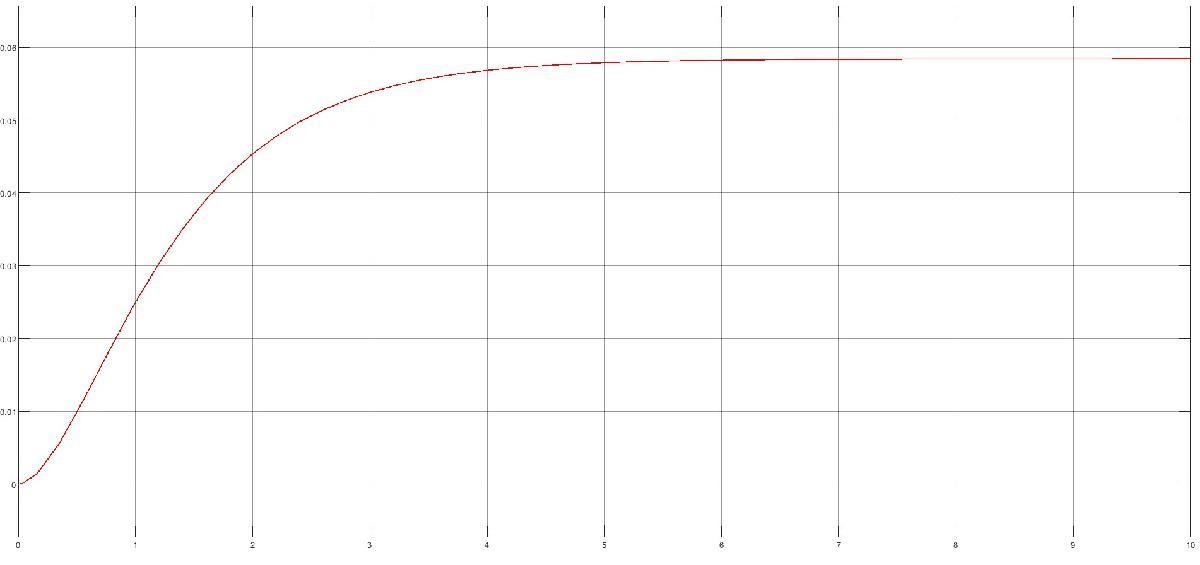

**Simluation for B(t) = 0.1 U/kg/h for a normal subject**

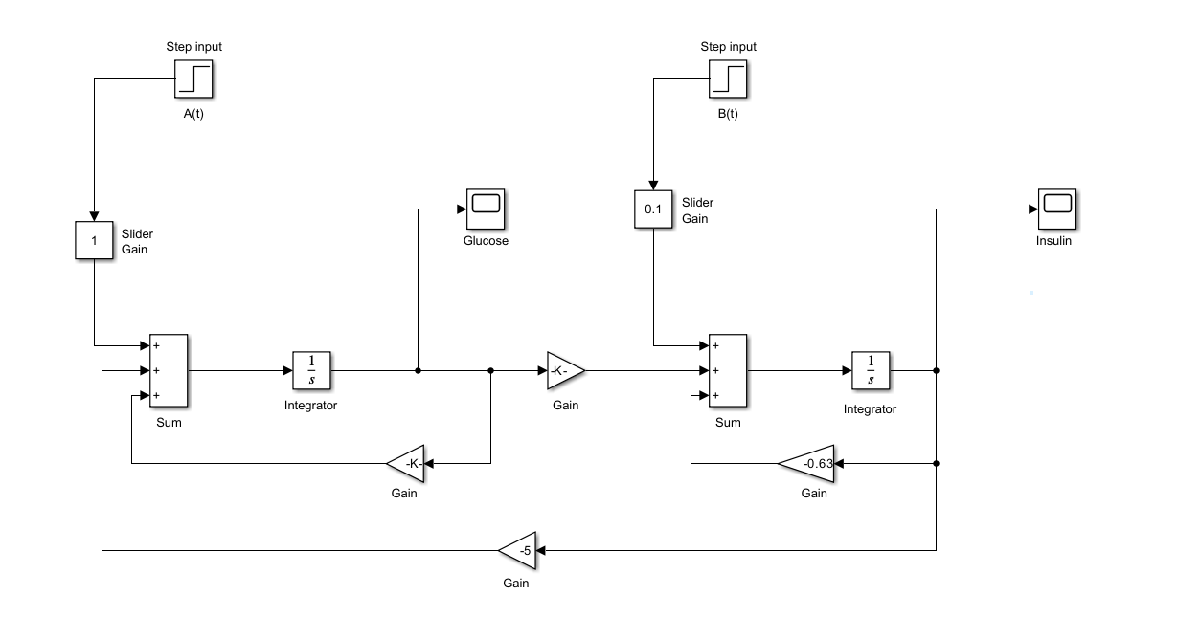

The results are as follows.

Glucose

Insulin

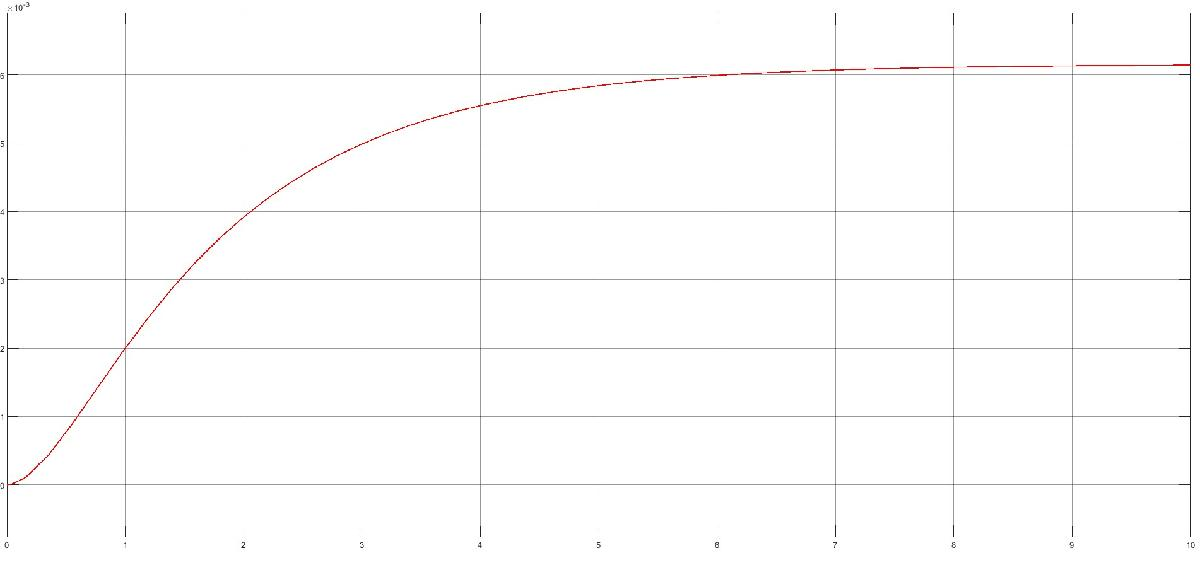

**Simluation for B(t) = 0.1 U/kg/h for a diabetcic subject**

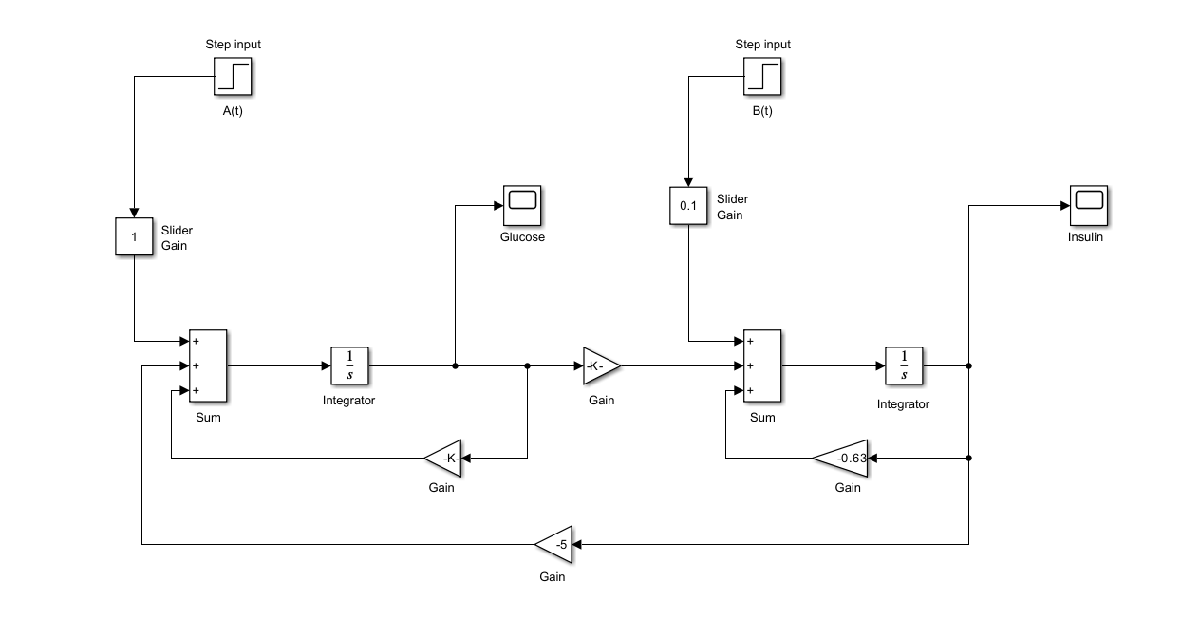

The results are as follows.

Glucose

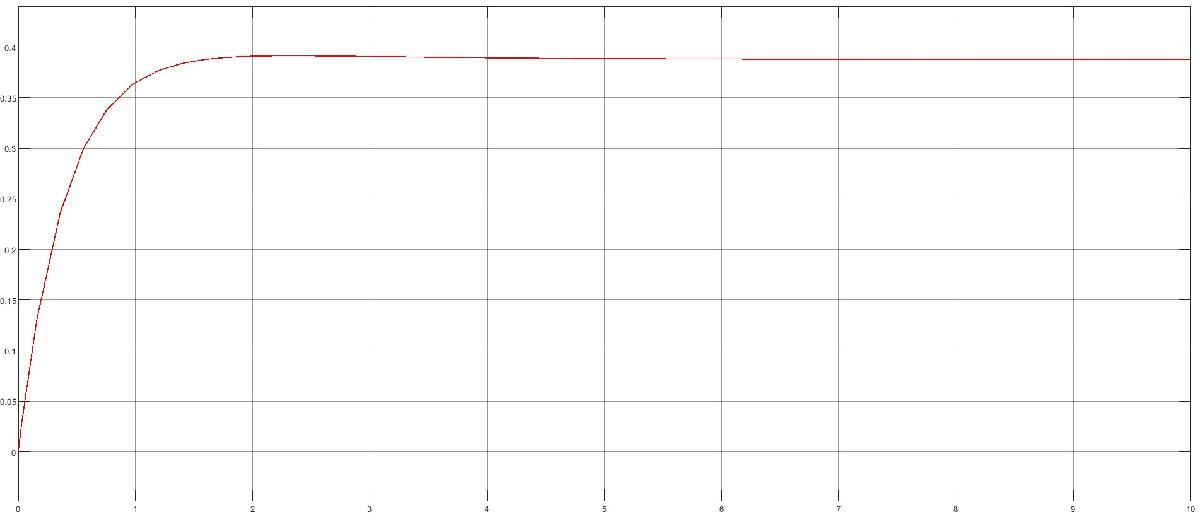

Insulin

#### Question 2

**Riggs model simulation **

The model is included in the *riggs_model.slx* file. 

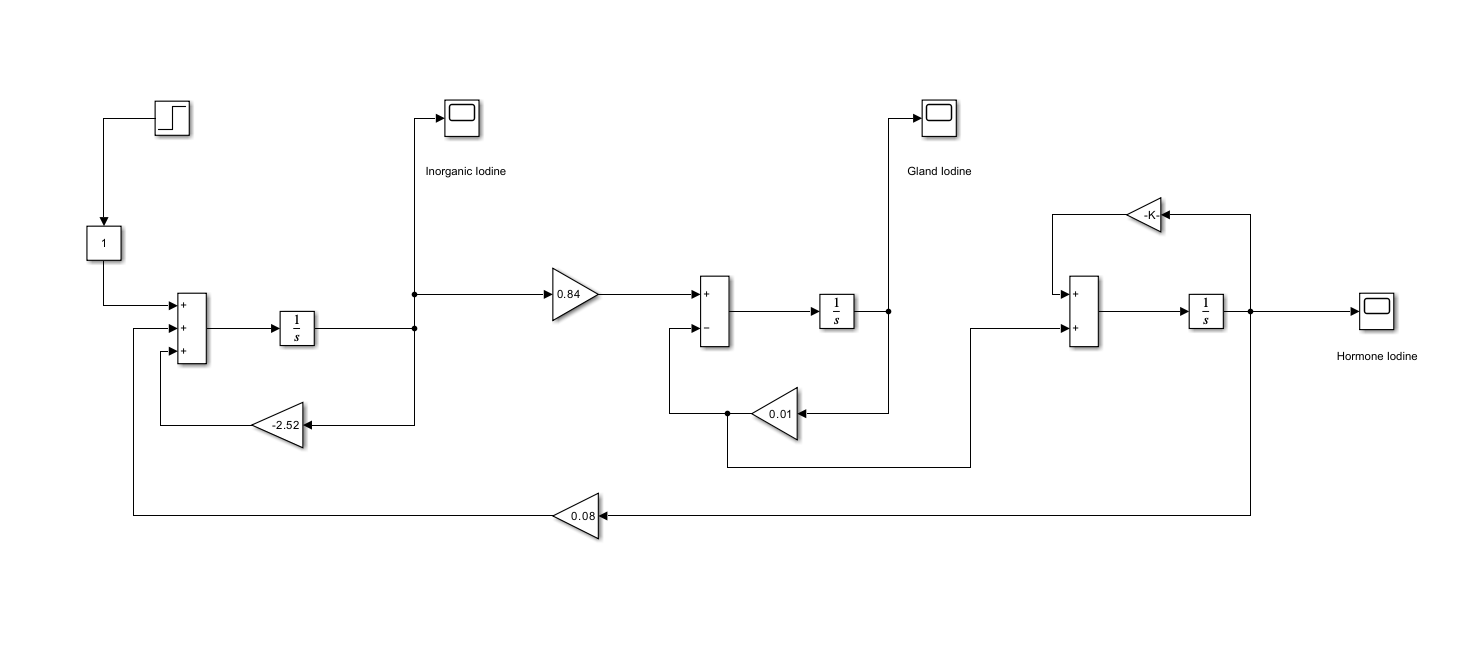

The results are as follows.

Inorganic Iodine

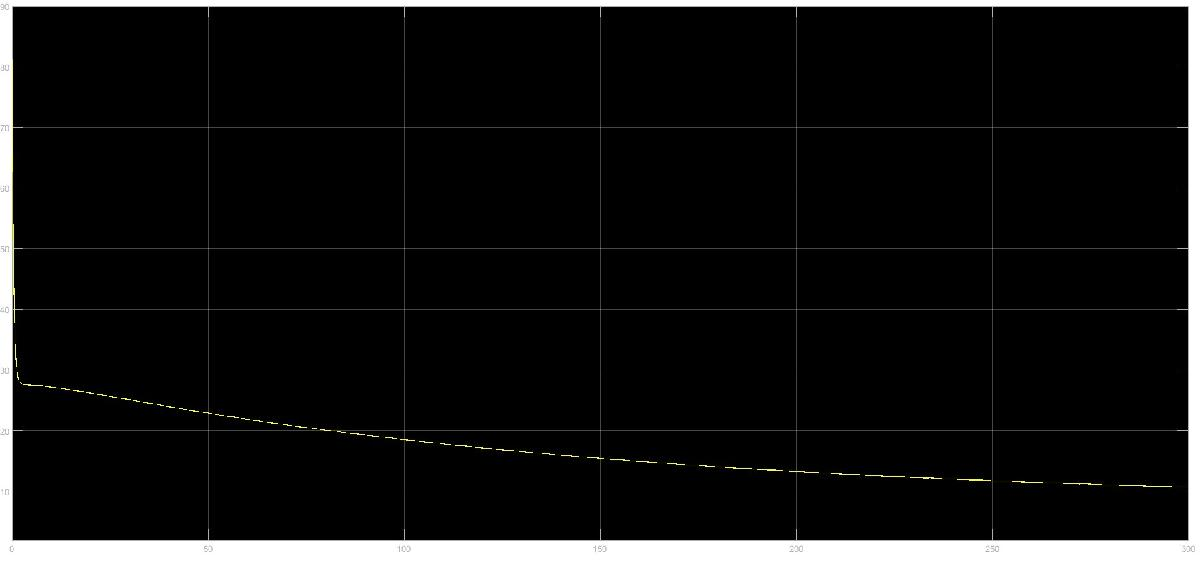

Gland Iodine

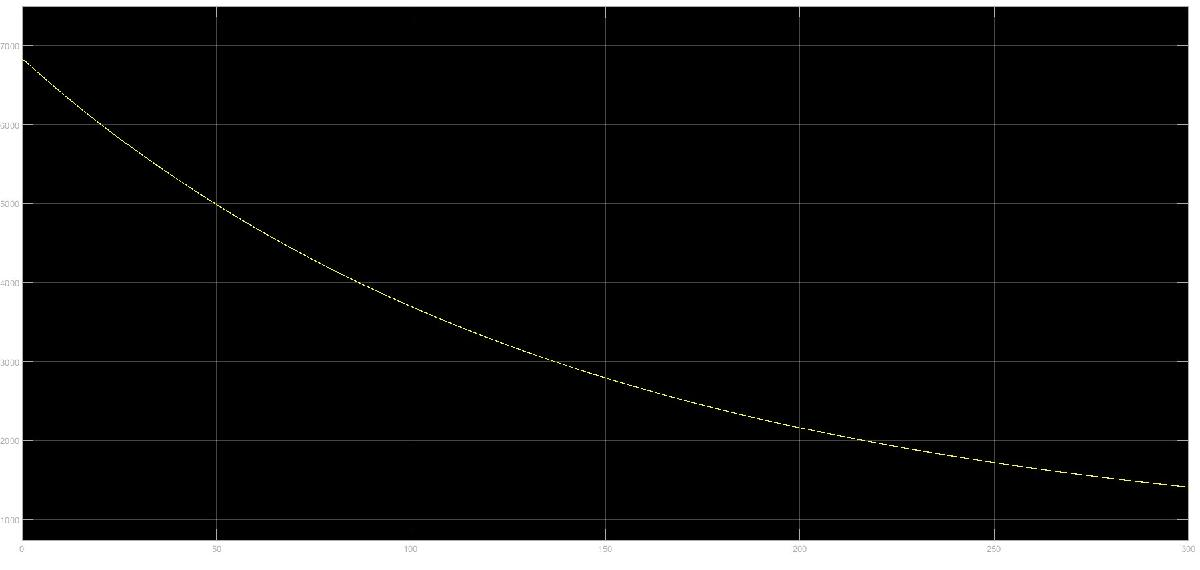

Hormonal Iodine

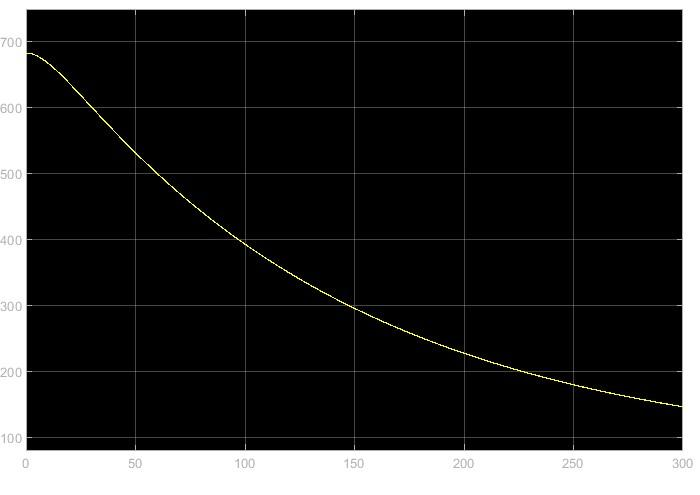

## Part 3

**Question 1**

**Deriving analytical solutions for the Bolies' glucose insulin model**

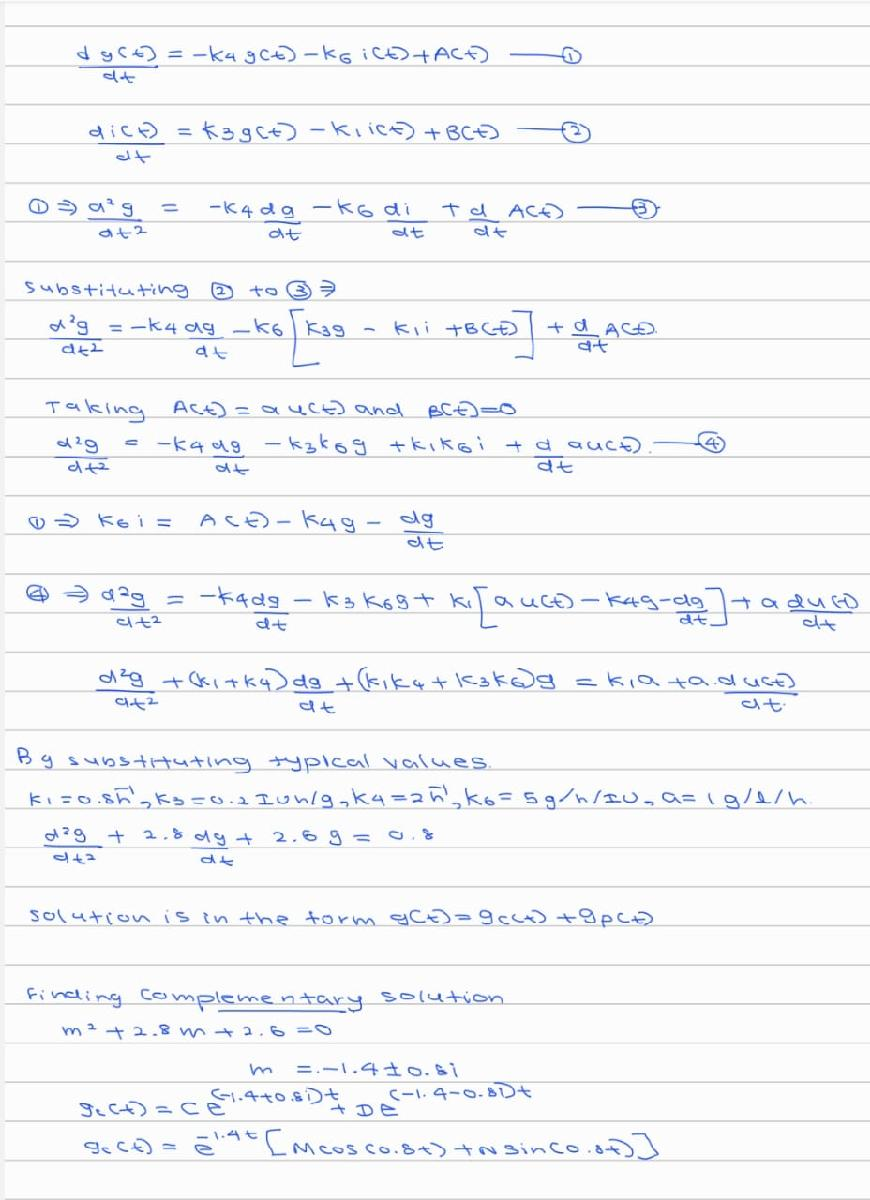

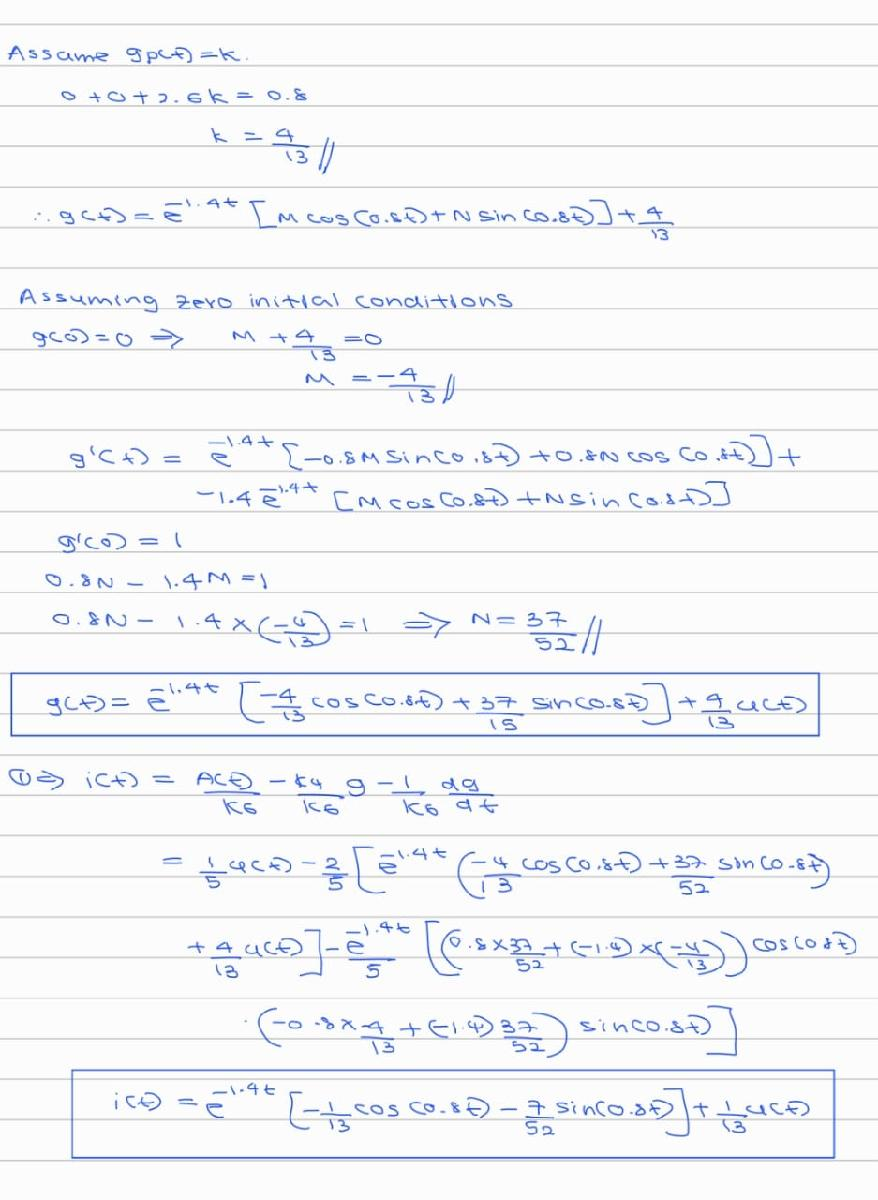

Plotting the results

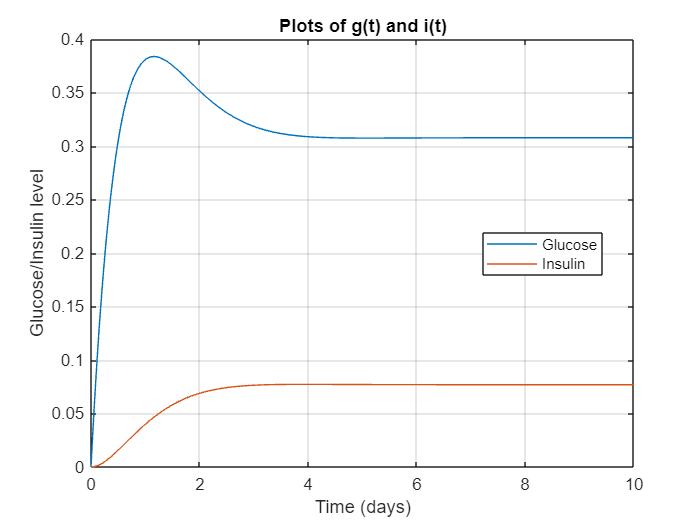

t = 0:0.01:10;
% Analytical solutions
g_t = (exp((-1.4).*t)).*(-(4/13)*cos((0.8).*t) + (37/52)*sin((0.8).*t)) + 4/13;
i_t = (exp((-1.4).*t)).*(-(1/13)*cos((0.8).*t) - (7/52)*sin((0.8).*t)) + 1/13;

figure;
plot(t,g_t,t,i_t);
grid on;
legend('Glucose','Insulin',"Location","best")
xlabel ('Time (days)');
ylabel ('Glucose/Insulin level');
title('Plots of g(t) and i(t)');

**Explanation in terms of the stability curve**

The graph illustrates how insulin and glucagon work together to control blood glucose levels. After a large intake of glucose, insulin levels increase rapidly, reaching their peak shortly after glucose levels rise. This is due to a brief delay as pancreatic cells take time to detect the elevated glucose and respond by releasing insulin.

When glucagon is present, the final glucose level remains higher than when glucagon is absent. This happens because glucagon opposes insulin’s effects by stimulating the liver to release stored glucose, which helps maintain elevated blood sugar levels.

Even though insulin secretion increases in response to glucagon, the opposing actions of the two hormones lead to a higher steady-state glucose level when glucagon is involved. This outcome aligns with the predictions made by Bolie’s model.

**Question 2**

**Expanding the Bolies' model by including the effects of glucagon**

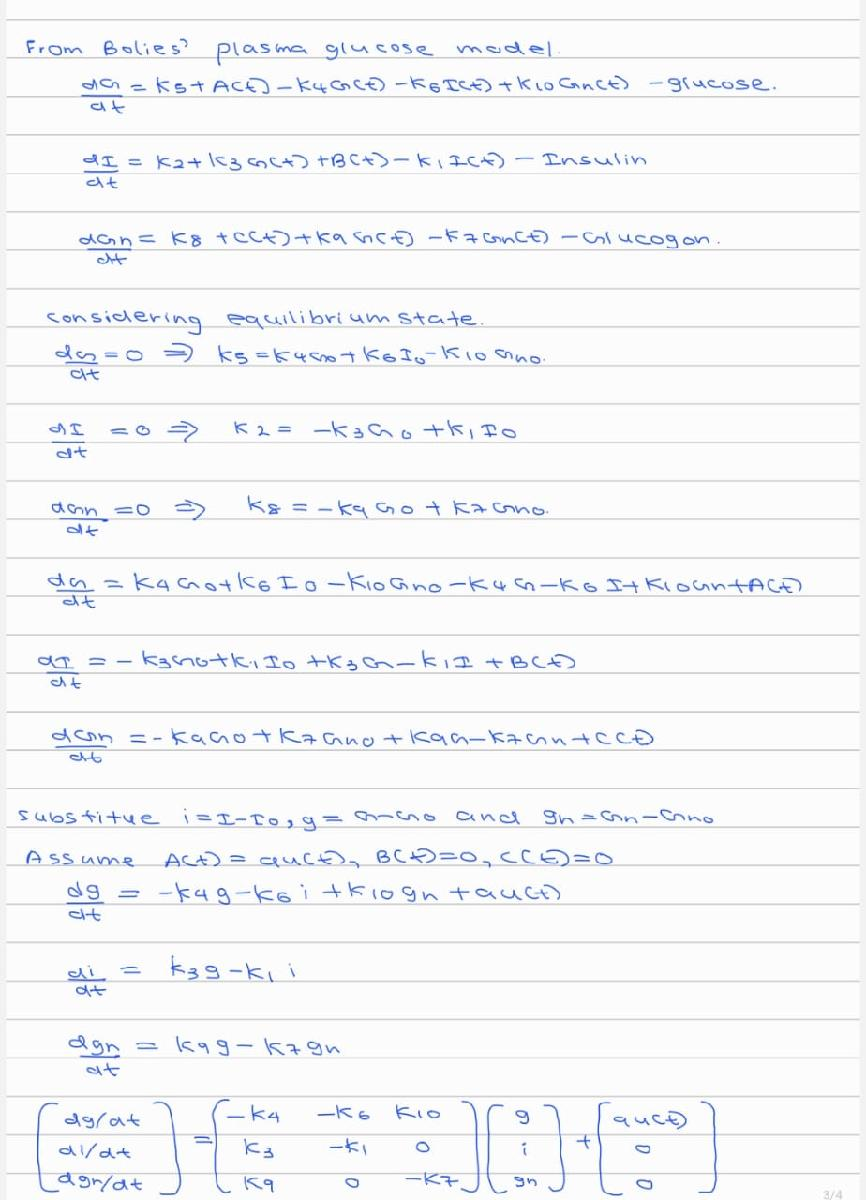

Expanded Bolies' model is included in the *bolies_model_with_glucogen.m* file as a function. The plotted solutions are as follows.

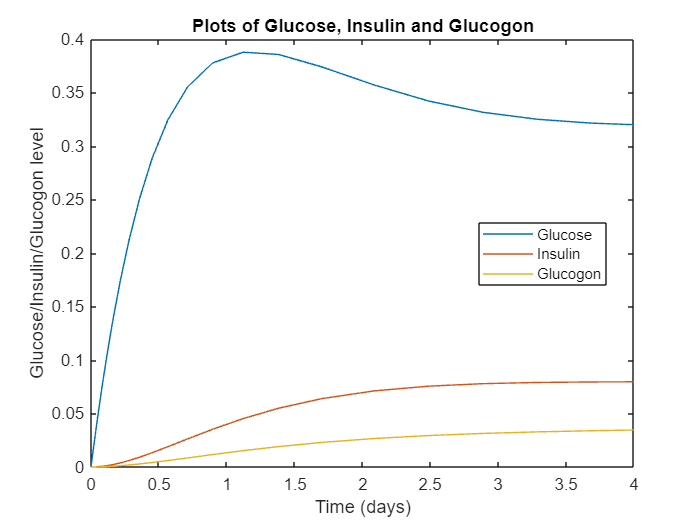

[t,y] = ode23('bolies_model_with_glucogen',[0 4],[0 0 0]);

figure;
plot(t,y)
legend('Glucose','Insulin','Glucogon','Location','best')
xlabel('Time (days)');
ylabel('Glucose/Insulin/Glucogon level');
title('Plots of Glucose, Insulin and Glucogon')